clc
format compact
syms theta pdynbar etheta etheta1 etheta2 etheta3
gama2=input('input_value_of_Kt_2=');
beta2=input('input_value_of_Ka_2=');
gama3=input('input_value_of_Kt_3=');
beta3=input('input_value_of_Ka_3=');
a=input('input_value_of_alpha(in degree)='); %alpha: angle of attack from Zero lift line(alphaZLL)
alpha=a*pi/180;
e=input('input_value_of_e(with sign)=');%distance between elastic axis and aerodynamic center
if (gama2==0)&&(beta2==0)
    a=' (Cubic Nonlinearity)';
    if gama3>0
        b='(structural hardening)';
    else
        b='(structural softining)';
    end
elseif (gama3==0)&&(beta3==0)
    a=' (Quadratic Nonlinearity)';
    if gama2>0
        b='(structural hardening)';
    else
        b='(structural softining)';
    end
else
    a=' (Combo Nonlinearity)';
    if (gama2>0)&&(gama3>0)
        b='(structural hardening)';
    else
        b='(structural softining)';
    end
end
%equilibrium equation:
if e>0
    eqn=(gama3+pdynbar*beta3)*theta^3+(gama2+pdynbar*(beta2+3*beta3*alpha))*theta^2+(1-pdynbar*(1-2*beta2*alpha-3*beta3*alpha^2))*theta-pdynbar*alpha*(1-beta2*alpha-beta3*alpha^2)==0;
elseif e<0
    eqn=(gama3-pdynbar*beta3)*theta^3+(gama2-pdynbar*(beta2+3*beta3*alpha))*theta^2+(1+pdynbar*(1-2*beta2*alpha-3*beta3*alpha^2))*theta+pdynbar*alpha*(1-beta2*alpha-beta3*alpha^2)==0;
end
%roots of equilibrium equation:
roots=solve(eqn,theta);
disp('Roots:')

Roots:


% roots in terms of pdynbar:
etheta1=roots(1) % etheta1 means equilibrium theta1

$$etheta1 = 0$$

etheta2=roots(2) % etheta2 means equilibrium theta2

$$etheta2 = \frac{10}{3}$$

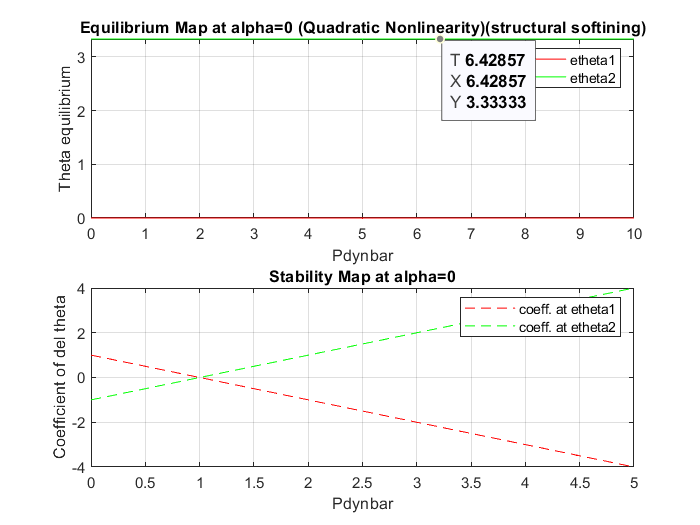

if (gama3~=0)&&(beta3~=0)
    etheta3=roots(3) % etheta3 means equilibrium theta3
end
%coefficient of del_theta=cdt
if e>0
    cdt=1+2*gama2*etheta+3*gama3*etheta^2-pdynbar*(1-2*beta2*(alpha+etheta)-3*beta3*(alpha+etheta)^2);
elseif e<0
    cdt=1+2*gama2*etheta+3*gama3*etheta^2+pdynbar*(1-2*beta2*(alpha+etheta)-3*beta3*(alpha+etheta)^2);
end
cdt1=subs(cdt,etheta,etheta1); %cdt1= coefficient of del_theta at etheta1
cdt2=subs(cdt,etheta,etheta2); %cdt2= coefficient of del_theta at etheta2
if (gama3~=0)&&(beta3~=0)
    cdt3=subs(cdt,etheta,etheta3); %cdt3= coefficient of del_theta at etheta3
end
figure
subplot(2,2,[1 2])
fplot(pdynbar,etheta1,[0,10],'r','DisplayName','etheta1')
hold on ; grid on
fplot(pdynbar,etheta2,[0,10],'g','DisplayName','etheta2')
if (gama3~=0)&&(beta3~=0)
fplot(pdynbar,etheta3,[0,10],'b','DisplayName','etheta3')
end
title(['Equilibrium Map at alpha=',num2str(alpha),a,b])
xlabel('Pdynbar')
ylabel('Theta equilibrium')
legend
subplot(2,2,[3 4])
fplot(pdynbar,cdt1,[0,5],'r--','DisplayName','coeff. at etheta1')
hold on; grid on
fplot(pdynbar,cdt2,[0,5],'g--','DisplayName','coeff. at etheta2')
if (gama3~=0)&&(beta3~=0)
fplot(pdynbar,cdt3,[0,5],'b--','DisplayName','coeff. at etheta3')
end
title(['Stability Map at alpha=',num2str(alpha)])
xlabel('Pdynbar')
ylabel('Coefficient of del theta')
legend